clear;clc;close all;fclose('all');

Parameters:

ZC_root = 13;
nfft = 4096;
ZC_length = nfft/2;

ZC Sequence:

sync_tx = exp(-1i*pi*ZC_root*(1:ZC_length).*((1:ZC_length)+1)/ZC_length);
sync_tx_zp = [zeros(1,(nfft-ZC_length)/2),sync_tx,zeros(1,(nfft-ZC_length)/2)];
sync_tx_time = ifft(ifftshift(sync_tx_zp),nfft);

Coefficients:

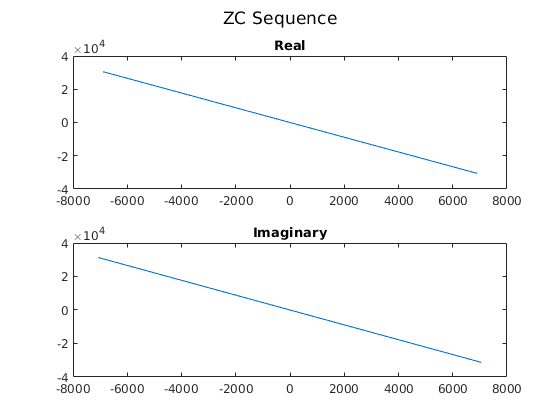

sync_coef = conj(fliplr(sync_tx_time));
sync_coef_i = real(sync_coef); sync_coef_q = imag(sync_coef);
max_val = max(sync_coef);
scaled_sync_coef_i = int16(sync_coef_i ./ max_val .* 32767);
scaled_sync_coef_q = int16(sync_coef_q ./ max_val .* 32767);
figure(),subplot(2,1,1),plot(scaled_sync_coef_i),title('Real')
subplot(2,1,2),plot(scaled_sync_coef_q),title('Imaginary'),sgtitle('ZC Sequence')

Write to coe files for Xilinx FIR compiler:

file = fopen('../Xilinx/Vivado/modules/data/zc_4096_nfft_2048_ZC_13_root_i.coe','w');
fprintf(file,"radix=10;\n");
fprintf(file,"coefdata=");
fprintf(file,"%d,",scaled_sync_coef_i(1:end-1));
fprintf(file,"%d;",scaled_sync_coef_i(end));
fclose('all');

file = fopen('../Xilinx/Vivado/modules/data/zc_4096_nfft_2048_ZC_13_root_q.coe','w');
fprintf(file,"radix=10;\n");
fprintf(file,"coefdata=");
fprintf(file,"%d,",scaled_sync_coef_q(1:end-1));
fprintf(file,"%d;",scaled_sync_coef_q(end));
fclose('all');